## MATLAB和PTB100问- Lecture 3 （2024.3.4）

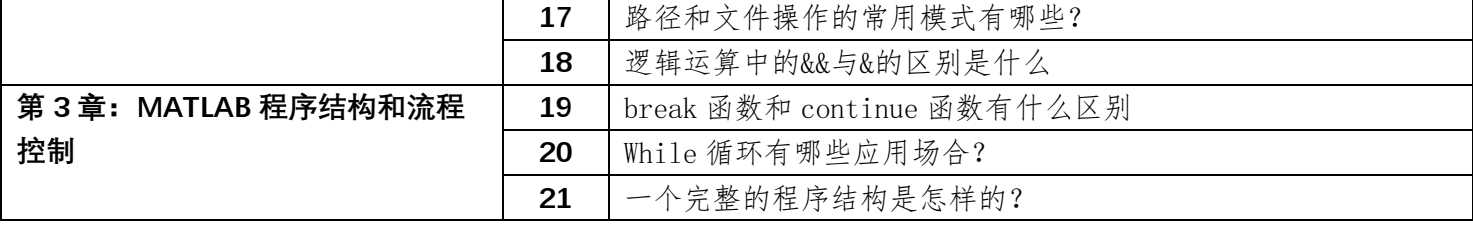

## **【教学目标】 **

## **1. 函数初步 -   输入和输出**

## **2.程序结构和设计- if,  for, while, try..catch.error**

## **3.程序调试- keyboard **

** 【复习】矩阵的索引**

** sort, ind2sub, accumarray  **

data = [1, 2, 3; 4, 5, 6; 7, 8, 9]; % 示例数据

writematrix(data, 'output.csv');

data = [1, 2, 3; 4, 5, 6; 7, 8, 9]; % 示例数据

无效表达式。调用函数或对变量进行索引时，请使用圆括号。否则，请检查不匹配的分隔符。


writematrix(data, 'output.xlsx');

data = {'Name', 'Age', 'Score'; 'John', 30, 85.5; 'Jane', 28, 90.2};

writecell(data, 'output.csv');

T = table({'John'; 'Jane'}, [30; 28], [85.5; 90.2], ...

    'VariableNames', {'Name', 'Age', 'Score'});

writetable(T, 'output.csv'); % 输出到CSV

writetable(T, 'output.xlsx'); % 输出到Excel

T1=readtable('output.xlsx');

function [avg, sum] = stats(input1,input2)
    % 这个函数返回一组数值的平均值和总和
    % 如果调用时没有请求总和，函数只计算平均值
     % 检查输入参数的数量
    if nargin < 2
        error('需要至少两个输入参数。');
    end

    % 计算总和
    sum = input1+input2;

    % 如果请求了两个输出，则还计算平均值
    if nargout > 1
        avg = sum/2;
    else
        avg = sum;  % 如果只请求了一个输出，只返回总和
    end
end

if unit=='i'
    len=len*2.54;
else
    len=len % this does nothing so skip it!
end

if unit=='i'
    len=len*2.54;
end

if number ==5
    disp('It is a 5');
elseif number ~= 5
    disp('It is not a 5')
end

if number ==5
    disp('It is a 5')
else
    disp('It is not a 5')
end

A1=[true,false,true];
A2=[true,true,false];
result=A1&A2
result2= A1&&A2

a = -5;
b = 10;

if (a > 0) && (b > a)  % 如果a大于0且b大于a，则执行以下语句
    disp('b is greater than a and a is positive');
end

function y = If_Example(x)
    if x == 0
        disp('The value of x is zero!');
    end
    if x > 3
        y = x^2;
    elseif 3 >= x && x >= 2
        % 3 >= x >= 2 错误
        y = x;
    else
        y = x - 3;
    end

function code = NestedIf (gender, score)
    if gender == 1
        if score > 60
            code = 1;
        else
            code = 0;
        end
    elseif gender == 0
        if score > 40
            code = 3;
        else
            code = 2;
        end
    end

 function [education_code gender_code] = Switch_Example(education,gender)
    switch education
        case 1
            education_code = 100;
        case 2
            education_code = 110;
        case 3
            education_code = 111;
        otherwise
            education_code = 0;
    end
    switch gender
        case 'Male'
            gender_code = 1;
        case 'Female'
            gender_code = 2;
        otherwise
            gender_code = 0;
    end

    function y = Switch_Error(x)
    switch x
        case x > 3
            y = x^2;
        case 3 >= x && x >= 2
            y = x;
        otherwise
            y = x - 3;
    end

    x=zeros(10,1);
for i=1:10
    x(i)=i^2;
end

y=zeros(1,6);
index=1;
for i=0:2:10
    y(index)=sqrt(i);
    index=index+1;
end

z=zeros(1,6);
index=1;
for i= y
    z(index)=i^2;
    index=index+1;
end

**常见问题**

(1)在for循环的第二种结构里,我们经常会遇到这样一个问题。例如循环中变量的初始值为1,步长2,终止值为8,那么很容易就可以看出来,该变量按照这样的步长增长,永远无法等于终止值(变量永远为奇数,而终止值则是偶数)。

index=1;
for i=1:2:8
    i 
    index = index+1;
end

可以看到,i最终的取值是7。

类似的,for循环中的步长也不一定非要是正数或者整数。

index=1;
for i=8.29:-0.520:3.29
    i 
    index = index + 1;
end

(2)在for循环的第三种结构里,变量会遍历一个一维向量内的所有元素取值。这里我们需要注意,该一维向量内的元素可以被拓展成字符或字符串(那么相应的,这个一维向量也就变成了一个一维元胞数组)。这一功能对于数据的处理非常有帮助。我们在进行实验数据记录的时候,往往会将被试的姓名作为文件名来保存结果。这时候如果想要批量地进行数据处理,我们可以通过for循环逐个读取文件,再统一进行处理。

问题:现在有5 个文件,文件名分别是“cc.mat” “pp.mat” “glj.mat” “lx.mat” “cmy.mat”。每个文件中存储着一个变量名为Result的矩阵,矩阵的大小为50×1。其中每一行代表一个试次中该试次被试的反应时。要求编写一段代码,分别计算5个被试的平均反应时。

clear all;
clc;
SubjectName= {'cc','pp','glj','lx','cmy'};
SubjectID =1;
ReactionTime=zeros(5,1);
for CurrentName= SubjectName
    FileName= [CurrentName{1} '.mat'];
    load(FileName);
    ReactionTime(SubjectID)= mean(Result(:));
    SubjectID = SubjectID +1;
end

**(3) for 循环的嵌套**

clear all;
clc;
SubjectName= {'cc','pp','glj','lx','cmy'};
SubjectID =1;
ReactionTime=zeros(5,2);%保存结果,每一行表示一个被试
for CurrentName= SubjectName
    FileName= [CurrentName{1} '.mat'];
    load(FileName);
    TrialType1=0;%某个被试完成第一种类型试次的数量
    TrialType2=0;%某个被试完成第二种类型试次的数量
    RTSum1=0;%某个被试第一种类型的试次中反应时总和
    RTSum2=0;%某个被试第二种类型的试次中反应时总和
    for i=1:50
        if Result(i,1)==1
            TrialType1 = TrialType1+1;
            RTSum1= RTSum1+ Result(i,2);
        else
            TrialType2= TrialType2+1;
            RTSum2= RTSum2+ Result(i,2);
        end
        ReactionTime(SubjectID,1)= RTSum1/TrialType1;
        ReactionTime(SubjectID,2)= RTSum2/TrialType2;
    end
    SubjectID = SubjectID +1;
end

每一个for循环必须以end结尾,所以强烈建议每次在使用循环结构的时候,首先写好循环结构的头和尾(即for和end),再编写循环内的代码。

**(4) break  和 continue**

我们可以发现,当使用break函数的时候,MATLAB只执行了前两个循环中的命令。这意味着当执行break函数的时候,循环直接终止。所以break函数的功能在于跳出所有的循环,直接终止当前循环。而使用continue函数的时候,MATLAB则跳过了第三个循环中的命令。这意味着当执行continue函数的时候,当前循环中止,但不影响后面循环的执行。熟练使用这两个函数可以帮助我们处理很多需要及时控制循环终止与否的程序。

limit = 0.8;
s = 0;

while 1
    tmp = rand;
    if tmp > limit
        break
    end
    s = s + tmp;
end

limit = 0.8;
s = 0;

while s<6
    tmp = rand;
    if tmp > limit
        continue
    end
    s = s + tmp;
end

## While的用法

a=rand*3+2;
LoopNumber=0;
while a<=100000
    a=a^2;
    LoopNumber= LoopNumber+1;
end

T1= GetSecs;
buttons=0;
while 1
    [x,y,buttons]= GetMouse;
    if sum(buttons)>0
        T2= GetSecs;
        disp(T2-T1);
        break;
    end
end

I=1;%预设声音的强度
d=0.5;% 声音持续时间500ms
sf=14400;% 采样率
f=500;% 频率
t=linspace(0,d,sf*d);
tone=sin(2*pi*f*t);% 设置声音
%以下用sound函数播放第一次声音
sound(tone,sf);
answer=input('Can you hear the tone?');% 键盘录入反应1-听到;2-听不清楚
while answer==1% 进入while循环
    I=I/2;% 如果回答“听到”,将声强减半
    sound(tone*I,sf);% 播放声音
    answer=input('Can you hear the tone?');
end
fprintf('The threshold is equal to %2.1f dBFs\n',20*log10(I));
% 在命令窗口返回阈值(模拟值)

## Try-Catch结构

try
    a=zeros(1,10);
    for i=0:10
        a(i)=i;
    end
catch
    disp('Error!');
end

 try
    clear all;
    clc;
    Screen('Preference','SkipSyncTests',1);
    [w,rect]= Screen('OpenWindow',0,[255 0 0]);
    T1=GetSecs;
    buttons=0;
    while 1
    [x,y,buttons]= GetMouse;
        if sum(buttons)>0
            T2=GetSecs;
            disp(T2-T1);
            Screen('CloseAll');
            break;
        end
    end
catch
    Screen('CloseAll');% 关闭当前窗口
    Priority(0);
    ShowCursor;
    psychrethrow(lasterror);% 输出错误信息
end

在MATLAB程序中使用keyboard函数可以在代码的特定位置插入一个暂停，使MATLAB进入交互模式。在此模式下，你可以手动执行命令来检查变量的值、修改变量或执行其他命令，以帮助调试程序。使用keyboard的一个简单示例是：

function testDebug()
            a = 1;
            b = 2;
            keyboard; % MATLAB在这里暂停，等待用户输入
            c = a + b;
            disp(c);
end

 在上述代码中，当MATLAB执行到keyboard命令时会暂停，此时命令窗口会变成交互模式，允许你检查变量a和b的值，或执行任何其他命令。要继续执行程序，可以使用dbcont命令；要退出调试模式，可以使用dbquit命令。